clc;
clear all;
addpath('../utils')

This script showcases the genStrlkOFDM function. In this playground, you can view a spectrogram, a power plot (PSD or Power vs time), and view a constellation plot of the sub-carrier data.

%--------------------------------------%
%----------------Option----------------%
%--------------------------------------%
specPlot_en = 1;
pwrPlot_en = 1;
constPlot_en = 1;
%--------------------------------------%
%----------------Params----------------%
%--------------------------------------%
NFFT = 2^10; % # of FFT points for spectrogram, if too many points, it is reduced later

You can choose the number of symbols, an SNR, a receiver sampling rate Fsr, a receiver center frequency, a CFO (beta), the modulation index, the modulation scheme,  and the channel center. 

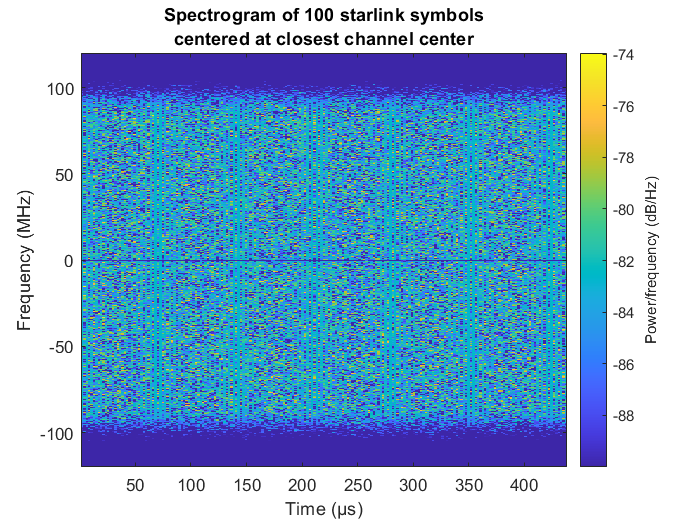

%--------------------------------------%
%---------OFDM Input params------------%
%--------------------------------------%d
s.Nsym = 100;
% Signal to noise ratio, in dB
s.SNRdB = nan();
% Receiver sample rate.  If this is less than Fs, then the signal is filtered
% before resampling to prevent aliasing.  Set Fsr to Fs to skip resampling.
s.Fsr = 200e6;
% Receiver center frequency, in Hz
s.Fcr = 12.075e9;
s.beta = 0; 
s.Midx = 4;
s.type = 'QAM';
s.Fc = 11.805e9;
%--------------------------------------%
%---------Generate Signal -------------%
%--------------------------------------%
y = genStrlkOFDM(s);

%--------------------------------------%
%---------Spectrogram -----------------%
%--------------------------------------%

if(specPlot_en)
    Stitle = {sprintf('Spectrogram of %d starlink symbols', s.Nsym),'centered at closest channel center'};
    F = 240e6/1024;
    chIdx = round((s.Fcr/1e9 - 10.7 - F/2/1e9)/0.25 + 0.5);
    Fcii = (10.7e9 + F/2 + 250e6*(chIdx - 0.5));
    plotSpec(y,0,0,s.Fcr,s.Fsr,Fcii,240e6,NFFT,Stitle)
end



%--------------------------------------%
%---------Power Plots -----------------%
%--------------------------------------%

if (pwrPlot_en)
    
    Stitle = {sprintf('Spectrogram of %d starlink symbols', s.Nsym),'centered at closest channel center'};
    plotPwr(y,20,0,length(y)/s.Fsr,s.Fsr,NFFT)
end

%--------------------------------------%
%---------Const Plots -----------------%
%--------------------------------------%
sc_mag_threshold = 0.95; % between 0 and 1;
if (constPlot_en)
    
    % resample and center to channel
    if (s.Fsr ~= 240e6)
        tVec = [0:length(y)-1]'/s.Fsr;
        [y,tVec] = resample(y,tVec,240e6);
    end
    if (getClosestFch(s.Fcr) - s.Fcr ~= 0)
        tVec = [0:length(y)-1]'/(240e6); 
        Fshift =  getClosestFch(s.Fcr) - s.Fcr;
        y = y.*exp(-j*2*pi*Fshift*tVec);
    end
    % zero pad
    yVec = [y; zeros((1056)*ceil(length(y)/(1056)) - length(y),1)];
    % remove CP
    y = reshape(yVec,1056,[]);
    y = y(32+1:end,:);
    % take FFT
    Y = 1/sqrt(1024).*fft(y);
    % find good subchannels
    idx = find(abs(Y)/max(abs(Y)) > sc_mag_threshold);

    % set gutter values to nan()
    Y(1:2,:) = nan();
    Y(end-1:end,:) = nan();
    [l,w] = size(Y);
    fprintf("Press any key to start constellation plotting loop...\n")
    pause;
    figure()
    for ii = 1:w
        plot(Y(idx,ii),"*");
        pause(1)
    end
    
end